# Detecção de Hotspots WiFi

#### Cadeira: Modelação e Simulação 2º Semestre 2019/2020

#### Trabalho de Laboratório nº 4

#### Alunos: Daniel Leitão 90042 - João Almeida 90119

#### Grupo: 2

#### Turno: Quarta-Feira 8:30-10:30

#### Docente: Alexandre Bernardino

## Inicialização, carregamento dos dados

Inicia-se o código pela chamada à função fornecida `MarkovChainDraw.m` que faz load da matriz de transição que é usada, dos dados das distâncias de cada agente e da posição da source. Adicionalmente exibe o grafo com os agentes no espaço e a suas ligações entre si. É sobre este grafo que grande parte do raciocínio, conjugado com os resultados que se obtem da análise da cadeia de Markov, é desenvolvido.

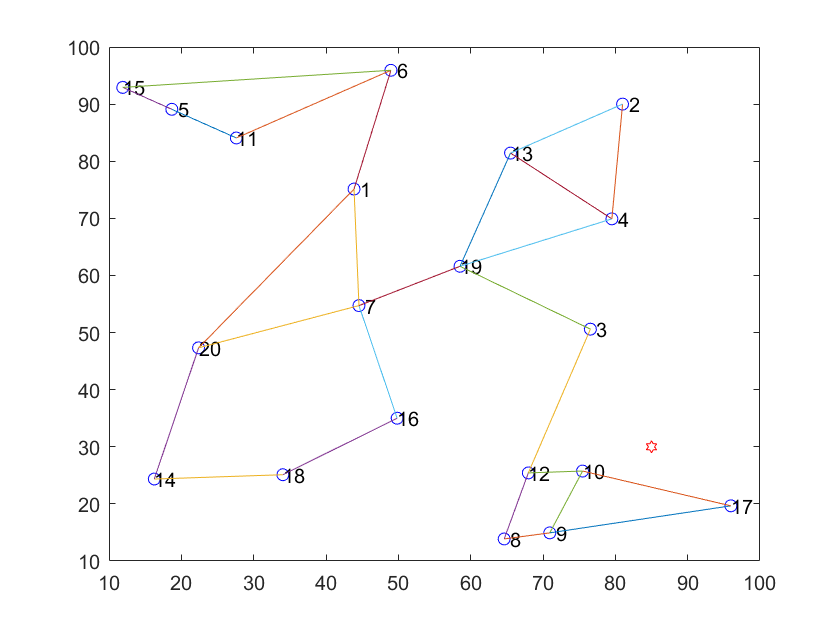

close all; clear;

% conteúdos: P - matriz de transição; nodePos - posição de cada estado;
% sourcePos - origem; e muitos mais...
run MarkovChainDraw.m; % load MarkovChain.mat feito aqui

## **Pergunta 2a - Distribuição de Equilíbrio**

O código para a resolução desta alínea é o seguinte:

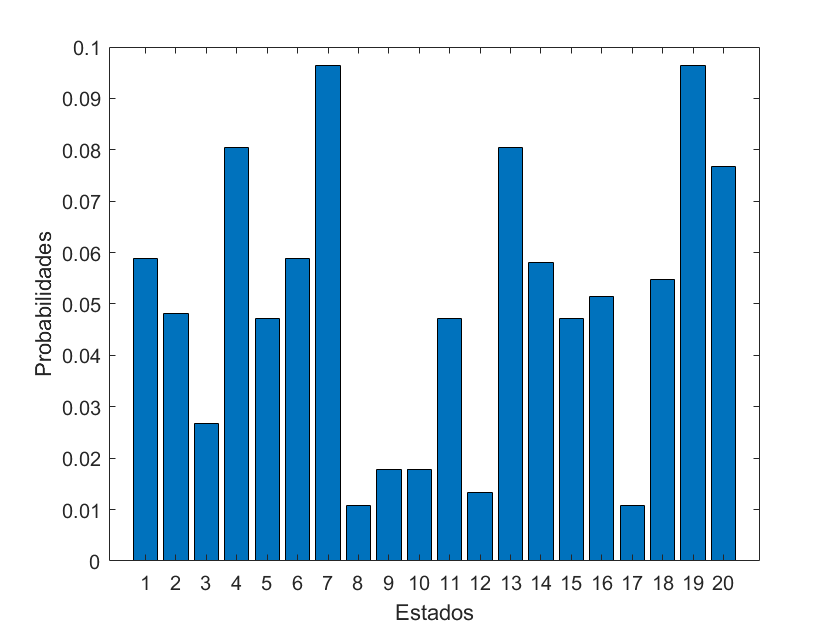

pi_eq = get_limiting_distribution(P);

figure(); clf;
bar(pi_eq);
set(gca,'XTick', 1:20);
xlabel("Estados");
ylabel("Probabilidades");

Após obter o vector da distribuição de probabilidades limite, faz plot do mesmo, que se encontra acima. Pode-se claramente observar que os estados (agentes) 7 e 19 são preponderantes em comparação com os restantes, o que faz sentido dado que atendendo ao gráfico os pontos 7 e 19 fazem a interligação entre subconjuntos do grafo, e a transição do token entre estes subconjuntos implica a transição do token entre estes dois estados. Já o 8 e o 17 são os estados menos prováveis e salta logo à vista que pertencem ao mesmo subconjunto: aquela "ilha" localizada perto da fonte de sinal. Uma situação deste género leva-nos a inquirir se o token circulará bem e vezes suficientes neste subconjunto definido por 3-12-10-8-9-17, mas ao analisar de novo o gráfico de barras acima percebemos que todos estes estados têm probabilidades limite bastante pequenas quando comparados com outros estados. Por isso é verdade que existe algum entrave à circulação do token neste subconjunto. A causa deste problema é explorada na alínea 2.d onde se procede também à sua correção para fins de otimização.

O importante neste pequeno trecho de código para calcular o vector distribuição limite é a função `get_limiting_distribution()` que é a seguinte:

dbtype("get_limiting_distribution.m");

1     function pi_eq = get_limiting_distribution(P)
2         % get vetor limit from probability matrix
3         
4         [V,D] = eig(P', 'vector');% eigenstuff
5     
6         [~,one_idx] = max(D); % idx do valor próprio máximo
7     
8         pi_eq = V(:,one_idx); % distr. eq. (desnorm.); vector próprio associado.
9         pi_eq = pi_eq/sum(pi_eq); % normalização (soma == 1)
10    end


O segredo passa por compreender como os valores próprios e vectores próprios estão relacionados com a matriz de transição. Outra forma de calcular a evolução da distribuição de probabilidades ao longo do tempo é:

$\pi(t+1) = P^T\pi(t)$ (de acordo com a notação empregue no enunciado)

O vector distribuição limite $\pi_{\infty}$ cumpre a condição seguinte:


$$\pi_{\infty} = P^T\pi_{\infty}$$


Significa isto que $\pi_{\infty}$ é vector próprio da matriz $P^T$ com valor próprio associado 1.

Sendo a matriz $P^T$ estocástica, os valores próprios são sempre menores ou iguais que 1, pelo que achar o vector próprio associado ao valor próprio máximo (que é 1) é suficiente para descobrir o vector distribuição de probabilidade limite.

Este vector deve ser normalizado para que a soma das probabilidades seja 1.

O código acima faz todo esse cálculo.

## Pergunta 2b - Geração de observações de RSS

Para gerar observações de RSS emprega-se o seguinte código:

nr_samples = 20; % 20 observações neste caso.
ni_v = normrnd(0,0.1,[1,nr_samples]); % geração de ruido aleatório
seq = state_seq_gen(P, nr_samples); % geração de uma run aleatória
[P_i,~,~] = RSS_m1(nodePos, sourcePos, seq, ni_v); % observações de RSS
T = table((1:nr_samples)', seq', ni_v', P_i,'VariableNames',{'Passo','Estado','Ruído','P_i'}); % tabela de valores
disp(T); % display 

    Passo    Estado      Ruído        P_i  
    _____    ______    _________    _______

      1        10      0.0020257    0.92012
      2        17        0.17817     0.5256
      3        10       0.085107    0.99983
      4        17       0.029566    0.45302
      5         9        0.11359    0.26366
      6        10       -0.11688    0.81697
      7         9       0.022649    0.24074
      8        17        0.17047    0.52157
      9         9         0.1903    0.28468
     10        17       0.027029    0.45188
     11        10       -0.21805    0.73836
     12         9      -0.093221     0.2144
     13         8       0.042747    0.15455
     14         9       -0.11837    0.20907
     15        10       0.045006    0.96053
     16        12       0.013404    0.32597
     17         8       0.088911    0.16185
     18        12        0.

A função `RSS_m1()` gera valores de P_i a partir da sequência de transição de estados gerada aleatóriamente e de acordo com a cadeia estabelecida; o método de geração é o método (1) do enunciado, i.e. o método real. Concretiza também a matriz A e o vector b para resolução do problema de mínimos quadrados, através das expressões (2) e (3) do enunciado.

dbtype("RSS_m1.m");

1     function [P_i, A, b] = RSS_m1(nodePos, sourcePos, seq, ni)
2         P_o = 100; % valor dado para P_o
3         ai = nodePos(seq,2:3); % elimina a primeira coluna (desnecessária...)
4         denom = sum((ai - sourcePos).^2,2); % denominador
5         
6         P_i = (P_o ./ denom) .* exp(ni'); % valor de P_i (disposição coluna)
7         A = [-2*P_i.*ai -ones(size(P_i)) P_i];
8         b = -P_i.*(sum(ai.^2,2));
9     end
10    
11    % gera valores de P_i a partir da sequência de transição de estados gerada
12    % aleatóriamente e de acordo com a cadeia estabelecida; o método de geração
13    % é o método (1) do enunciado, i.e. o método real. 
14    %
15    % nota importante: as variáveis passadas para funções não são editadas
16    % (estilo C, são cópias). Isto é importante por causa da linha 3.


Outra função importante que foi elaborada é a `state_seq_gen()` que a partir da matriz de transições e de um estado inicial aleatório (ou explicito) gera um número fixo de transições de estado, transições essas que são ponderadas em termos de probabilidade pela mesma matriz de transições.

dbtype("state_seq_gen.m");

1     function seq = state_seq_gen(P, nr_samples,init)
2         seq = zeros(1,nr_samples); % alloc, faster...
3         
4         if nargin > 2 % start pos, first entry
5             seq(1) = init; 
6         else
7             seq(1) = randi(20); 
8         end
9     
10        for i = 2:nr_samples % retrieving the rest of the samples, according to P
11            seq(i) = datasample(1:20,1,'Weights',P(seq(i-1),:));
12        end
13    end


Porém, para elevadas observações, resolver o problema de mínimos quadrados torna-se algo pesado computacionalmente, pelo que há necessidade de reduzir o número de linhas da matriz A e do vector b. A solução é concretizar uma versão ponderada deste problema, em que cada linha, única a um estado, tem um peso associado, ou seja, é multiplicada por um factor de peso. É relativamente fácil e intuitivo perceber que este factor para cada estado é o seu valor limite de probabilidade retirado do vector de distribuição limite. A razão para tal é que para um número elevado de passos na run, é espectável ver uma distribuição de estados idêntica à distribuição limite, distribuição essa que é presente nas linhas da matriz A, com cada linha associada à observação num dado estado. Pode-se então concatenar a matriz e introduzir um factor de peso. Há apenas que ter em atenção o ruído observado, que deve ser observado múltiplas vezes por estado de modo a anular o erro causado pelo mesmo. Isto implica alterações no método calculado pela função `RSS_m1()` e surge então a função `RSS_weighted():`

dbtype("RSS_weighted.m");

1     function [P_i, A, b] = RSS_weighted(nodePos, sourcePos, pi_eq, acc_fac)
2         P_o = 100; % valor dado para P_o
3         ai = nodePos(:,2:3); % elimina a primeira coluna (desnecessária...)
4         denom = sum((ai - sourcePos).^2,2); % denominador
5         
6         ni = sum(normrnd(0,0.1,[acc_fac,numel(pi_eq)]))/acc_fac;
7         disp(size(ni));
8         P_i = (P_o ./ denom) .* exp(ni'); % valor de P_i (disposição coluna)
9         A = [-2*P_i.*ai -ones(size(P_i)) P_i];
10        b = -P_i.*(sum(ai.^2,2));
11        
12        factor = diag(pi_eq);
13        A = factor * A;
14        b = factor * b;
15    end


Para a função é passada precisamente o vector distribuição limite (pi_eq) e um factor de precisão (acc_fac) para refinar o total de ruído ponderado por estado. De resto é aplicado o mesmo metodo para calcular os elementos da matriz A e vector b.

Consegue-se então resolver o problema:

[~,A,b] = RSS_weighted(nodePos, sourcePos, pi_eq, 20);

  Column 1

     1

  Column 2

    20




RlsPar = struct('lam',1); % algoritmo para determinar parâmetros
[e,w,RlsPar] = qrrls(A,b,RlsPar);

disp(['Distância entre source e estimado: ' num2str(norm(sourcePos'-w(1:2)))]); % distância entre source e estimado w (RLS)

Distância entre source e estimado: 0.10542


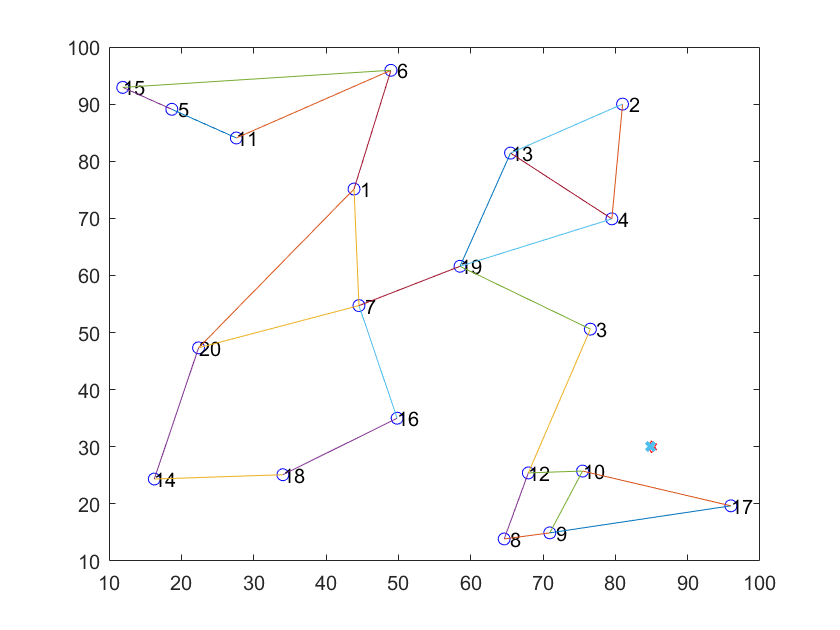


run MarkovChainDraw.m
plot(w(1),w(2),'x', 'LineWidth', 2); % plot do estimado w (RLS)

A função `qrrls()` é nos fornecida para resolver o problema de mínimos quadrados, em alternativa poder-se-ia usar `w = A\b.`

A cruz azul dá-nos a estimativa por este método, para um factor de precisão 20, numa determinada run aleatória. Verifica-se que é uma estimativa bastante boa, geralmente.

## Pergunta 2c - Evolução das probabilidades

Usou-se o seguinte trecho de código para esta questão:

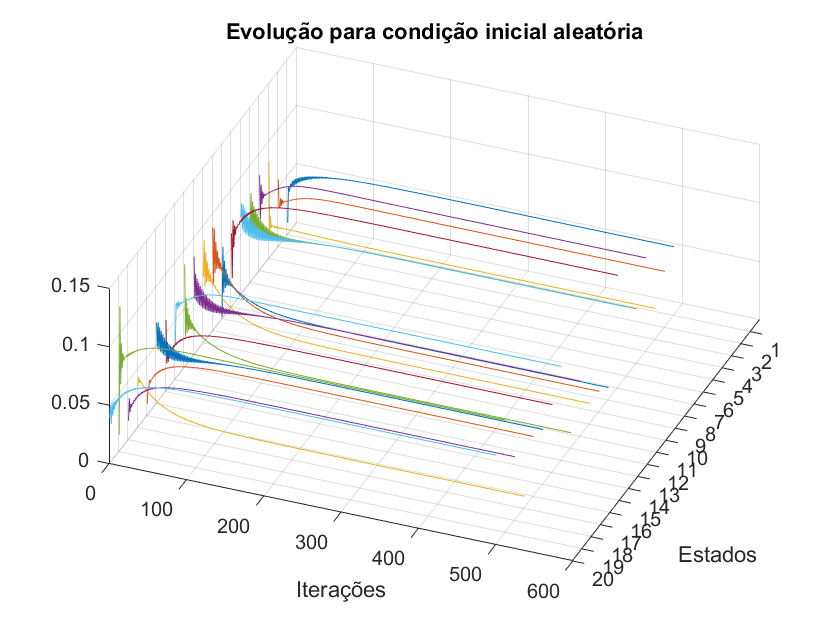

pi0a = randi(100,1,20); % gera aleatóriamente as probabilidades
pi0a = pi0a/sum(pi0a);

pi0b = zeros(1,20)+1/20; % vector com probabilidades iguais

pi0c = zeros(1,20);
pi0c(13) = 1; % inicia no estado 13

n = 500; % nr de aplicações da matriz P (passos)
pi_ta = zeros(n+1,20); 
pi_tb = zeros(n+1,20);
pi_tc = zeros(n+1,20);

pi_ta(1,:) = pi0a;
pi_tb(1,:) = pi0b;
pi_tc(1,:) = pi0c;
for i = 2:n+1 % aplicações sucessivas de P
    pi_ta(i,:) = pi_ta(i-1,:) * P;
    pi_tb(i,:) = pi_tb(i-1,:) * P;
    pi_tc(i,:) = pi_tc(i-1,:) * P;
end

figure(); clf;
MarkovTime(pi_ta,''); 
set(gca,'XTick',1:20);
xlabel("Estados");
ylabel("Iterações");
title("Evolução para condição inicial aleatória");
view([111.9909 56.0635]);


% verifica se para cada t, a soma das probabilidades é 1. 
% tolerância de 1e-10
all_lines_1 = isequal(round(sum(pi_ta,2),10),ones(n+1,1));
display(['[Caso 1] Soma igual a 1 para todo o t? (1 - sim, 0 - não): ' num2str(all_lines_1)]);

[Caso 1] Soma igual a 1 para todo o t? (1 - sim, 0 - não): 1


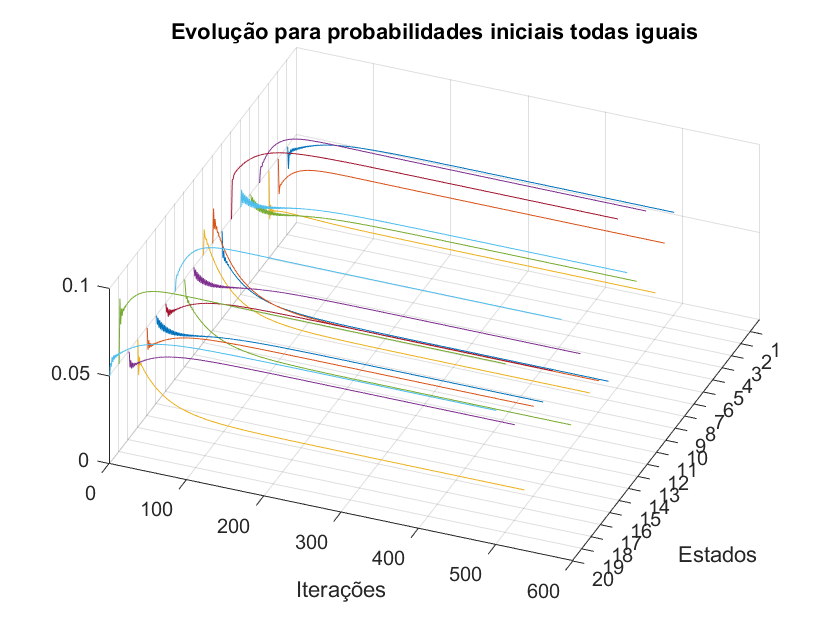


figure(); clf;
MarkovTime(pi_tb,''); 
set(gca,'XTick',1:20);
xlabel("Estados");
ylabel("Iterações");
title("Evolução para probabilidades iniciais todas iguais");
view([111.9909 56.0635]);


all_lines_1 = isequal(round(sum(pi_ta,2),10),ones(n+1,1));
display(['[Caso 2] Soma igual a 1 para todo o t? (1 - sim, 0 - não): ' num2str(all_lines_1)]);

[Caso 2] Soma igual a 1 para todo o t? (1 - sim, 0 - não): 1


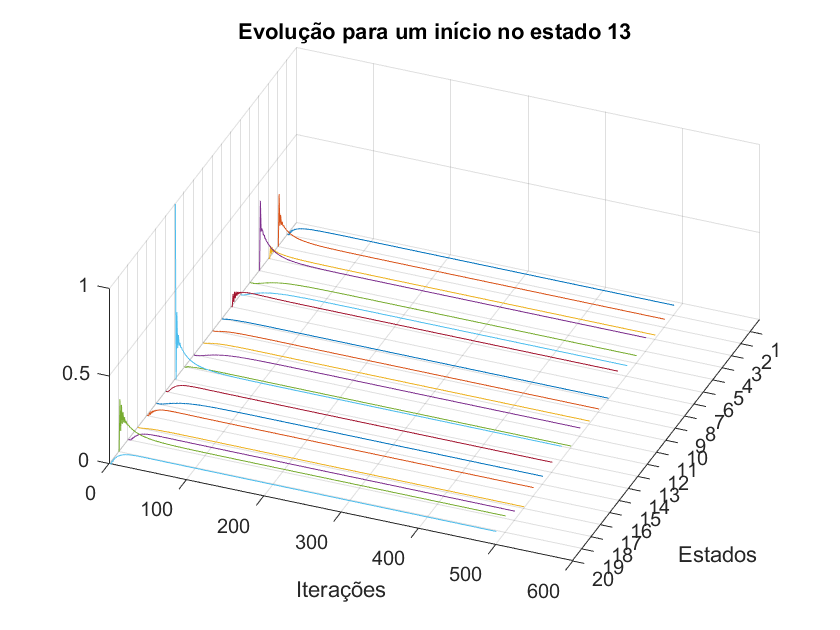


figure(); clf;
MarkovTime(pi_tc,'');
set(gca,'XTick',1:20);
xlabel("Estados");
ylabel("Iterações");
title("Evolução para um início no estado 13");
view([111.9909 56.0635]);


all_lines_1 = isequal(round(sum(pi_ta,2),10),ones(n+1,1));
display(['[Caso 3] Soma igual a 1 para todo o t? (1 - sim, 0 - não): ' num2str(all_lines_1)]);

[Caso 3] Soma igual a 1 para todo o t? (1 - sim, 0 - não): 1


Definiram-se 3 condições iniciais diferentes. A primeira é para $\pi_0
$ sendo aleatório. A segunda atribui probabilidades todas iguais à partida. A terceira força o estado 13 como sendo o ponto de partida.

Os resultados são iguais para os diversos casos, culminando na convergência para valores limite nos 3 casos.  É relevante tentar perceber que valores limite são estes, recorrendo ao gráfico de barras como já foi feito anteriormente:

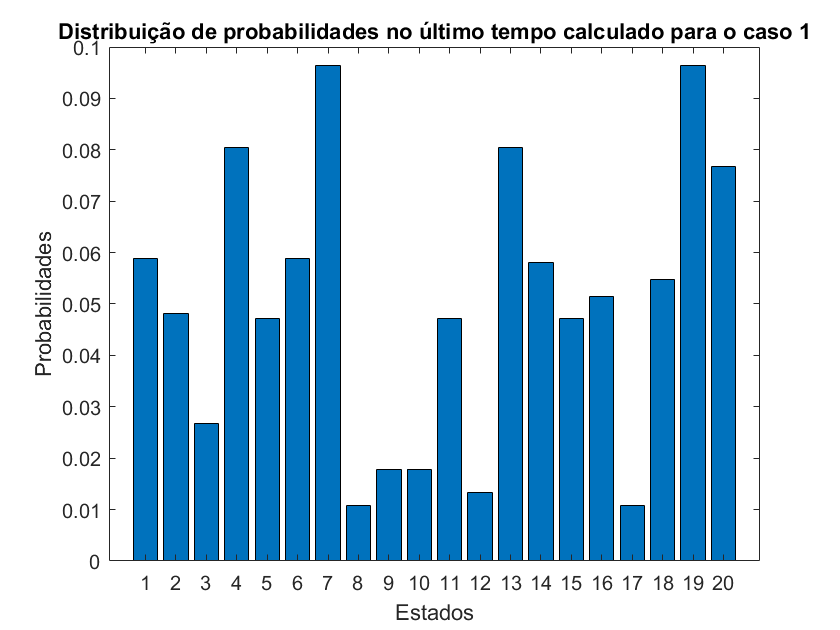

figure(); % caso 1
bar(pi_ta(n+1,:));
set(gca,'XTick', 1:20);
xlabel("Estados");
ylabel("Probabilidades");
title("Distribuição de probabilidades no último tempo calculado para o caso 1");

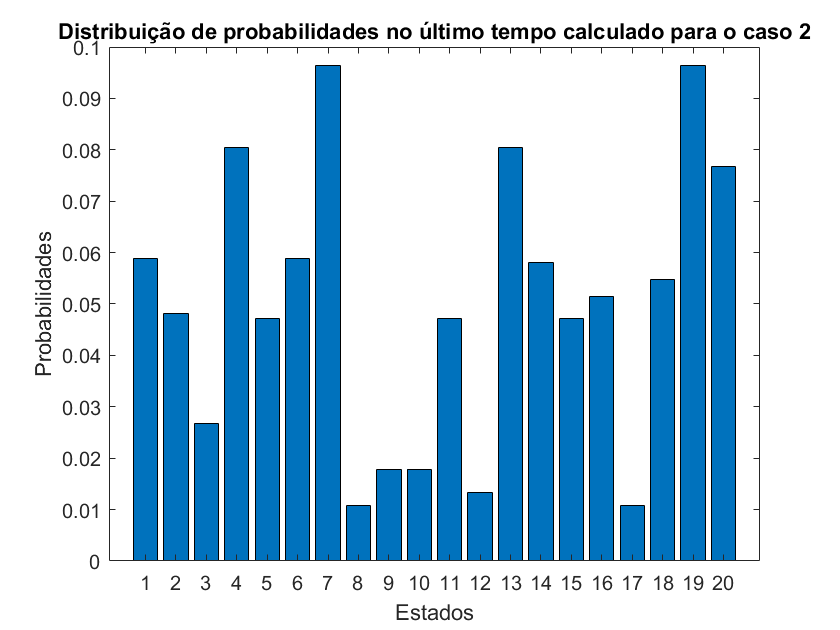


figure(); % caso 2
bar(pi_tb(n+1,:));
set(gca,'XTick', 1:20);
xlabel("Estados");
ylabel("Probabilidades");
title("Distribuição de probabilidades no último tempo calculado para o caso 2");

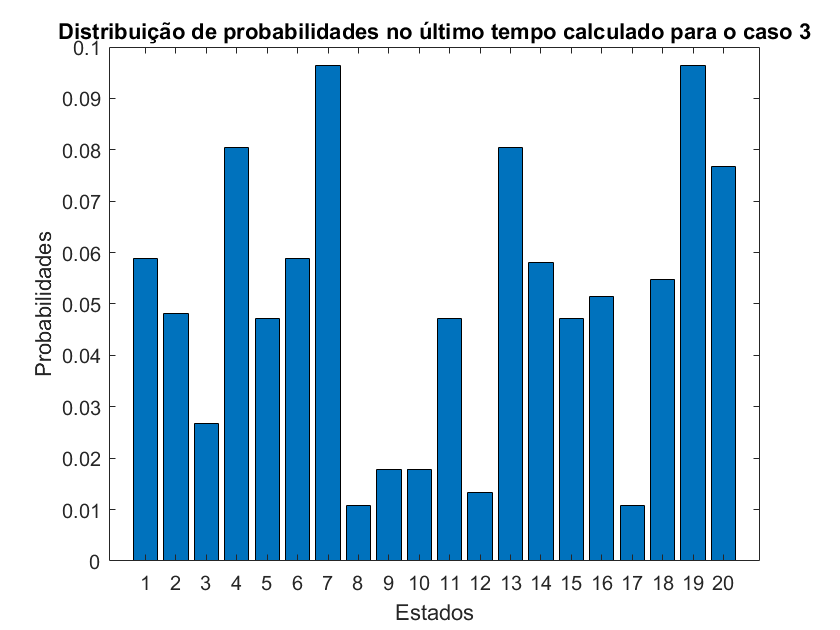


figure(); % caso 3
bar(pi_tc(n+1,:));
set(gca,'XTick', 1:20);
xlabel("Estados");
ylabel("Probabilidades");
title("Distribuição de probabilidades no último tempo calculado para o caso 3");

Como podemos ver, todos os casos apresentam o mesmo gráfico, pelo que convergem para o mesmo limite.

Este valor limite, é o mesmo calculado na alínea 2a, pelo que os gráficos são muito idênticos ao gráfico exibido nessa mesma alínea, o que nos prova a convergência para este valor limite para qualquer condição inicial que possamos definir. 

## Pergunta 2d - Teste de possíveis otimizações

Procura-se agora fazer alterações na cadeia de modo a que se possa otimizar a precisão da estimativa.

Na primeira pergunta evidenciou-se que um dado conjunto de pontos aparentava uma pequena probabilidade no limite, o que era indicador de dificuldades na passagem do token por aqueles estados. De facto, o problema está na passagem do token do estado 3 para o estado 12, que tem uma probabilidade de 0.1, face à transição 3-19 que tem uma probabilidade de 0.9. O que isto causa é sempre que o token está no estado 3, em vez de avançar para o subconjunto (ilha) perto do token, vai preferencialmente retornar, causando pouca circulação de modo geral nesse conjunto. Pouca circulação equivale a pouca recolha de informação numa dada área, o que se traduz em menor precisão da estimativa. Um raciocinio semelhante pode ser feito do estado 1 para o estado 6.

Tendo em vista as 3 alterações que se podem efectuar, optou-se por melhorar as seguintes:

- Aumentar a probabilidade 3-12 (diminui 3-19): maior otimização, tem em vista aumentar a circulação do token num subconjunto.

- Aumentar a probabilidade 19-3 (diminui 19-4 e 19-13): esta pequena otimização tem em vista aumentar a probabilidade com que o token atinge o estado 3 em detrimento de outro subconjunto definido pelos acessos 4-13 (conjunto [13,4,2])

- Aumentar a probabilidade 1-6 (diminui 1-7 e 1-20): semelhante à primeira otimização, mas para o subconjunto mais afastado da source (definido por [6,11,15])

Para averiguar se estas alterações produzem resultado, para além da precisão aumentada, há necessidade de quantizar a melhoria. O critério que implementamos é a entropia, calculada da seguinte forma a partir do vector distribuição limite de uma matriz de transição, para N estados:


$$S=-{\left(\pi_i \right)}_{\infty } \sum_{i\;=1}^N {\log \left(\pi_i \right)}_{\infty } \;$$


Para este cálculo usa-se a função `entropy()`.

disp(['Entropia ótima: ' num2str(entropy(zeros(1,20)+1/20))]);

Entropia ótima: 2.9957


disp(['Entropia da cadeia: ' num2str(entropy(pi_eq))]);

Entropia da cadeia: 2.839


A entropia ótima coincide com a distribuição em que o vector limite tem todos os estados com igual probabilidade. Isto significa que a circulação é eficiente e equilibrada por todos os estados, o que se traduz em, regra geral, alcançar uma precisão elevada em poucos passos. Compara-se com a entropia associada à matriz P (obviamente, menor).

O código empregue para implementar a primeira otimização é o seguinte: (NOTA: Recorre-se às mesmas funções que se utilizaram na pergunta 2b para gerar observações de RSS)

P_opt = P;
P_opt(3,19) = 0.65; P_opt(3,12) = 0.35;
P_opt(1,6) = 0.3; P_opt(1,7) = 0.35; P(1,20) = 0.35;
P_opt(19,3) = 0.4; P_opt(19,4)= 0.2; P_opt(19,13) = 0.2;

pi_eq_opt = get_limiting_distribution(P_opt);

disp(['Entropia da cadeia alterada (melhorias): ' num2str(entropy(pi_eq_opt))]);

Entropia da cadeia alterada (melhorias): 2.9618


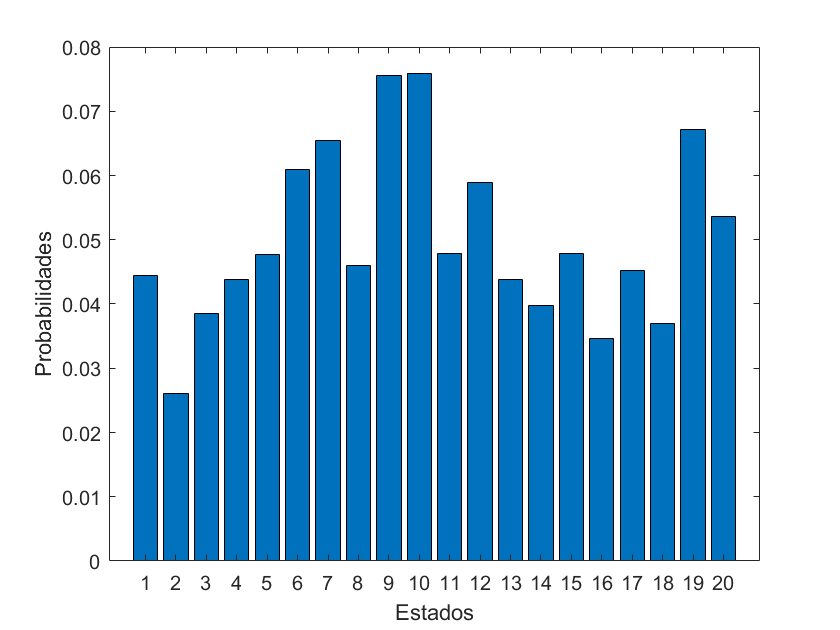


figure(); clf;
bar(pi_eq_opt);
set(gca,'XTick', 1:20);
xlabel("Estados");
ylabel("Probabilidades");

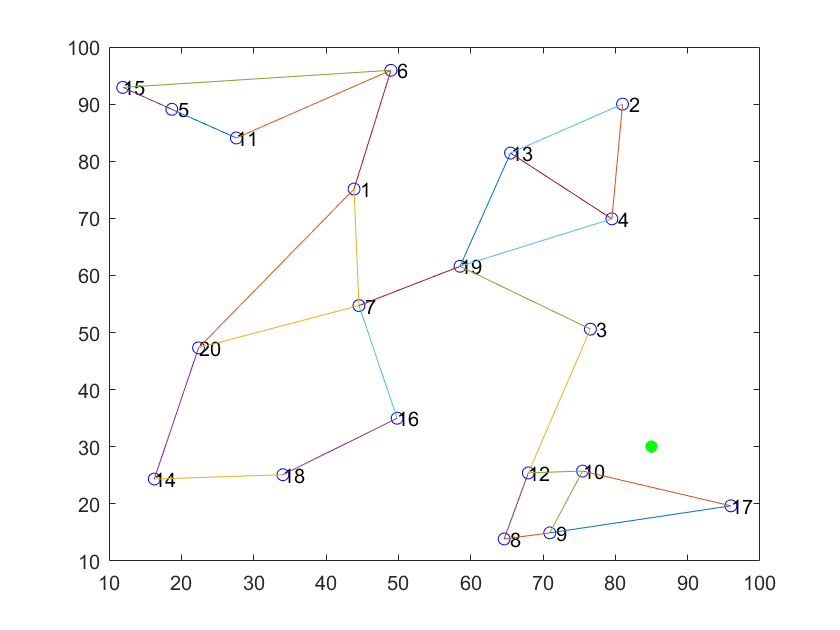


nr_samples = 1000;

ni_v = normrnd(0,0.1,[1,nr_samples]);
seq = state_seq_gen(P_opt, nr_samples);
[~,A,b] = RSS_m1(nodePos, sourcePos, seq, ni_v); % gera RSS via metodo 1

z = A\b;

run MarkovChainDraw.m
plot(z(1),z(2),'g*', 'LineWidth', 2); % plot do estimado z

O que salta logo à vista é um aumento da entropia, pelo que teoricamente obter-se-á melhores resultados em termos de precisão em pouco tempo. Marca-se com um circulo verde a posição estimada para a fonte, que se verifica ser bastante precisa! Analisando o gráfico de barras que mostra o vector limite de distribuição, vemos que os desiquilibrios são menores, o que também é coerente com um aumento da entropia e consequentemente com um aumento da precisão.

Põe-se agora um problema diferente. Com as mesmas 3 alterações, prejudicar a precisão da estimativa.

A estratégia empregue incide sobre restringir a circulação do token prioritáriamente ao conjunto [6,15,5,11] , que estão bastante afastados da fonte e rigurosamente com distâncias semelhantes. Tal fará com que a precisão desça bastante, tal como a entropia.

As alterações são as seguintes:

- Diminuir bastante a probabilidade 6-1, para que o token preferencialmente circule dentro do conjunto.

- Diminuir simultaneamente a probabilidade das transições 1-7 e 1-20 para que quando o token atinja o agente 1, siga preferencialmente para 6 de seguida.

O código que reflete estas alterações é o seguinte:

P_jam = P;

P_jam(6,1) = 0.02; P_jam(6,11) = 0.49; P_jam(6,15) = 0.49;
P_jam(1,6) = 0.98; P_jam(1,20) = 0.01; P_jam(1,7) = 0.01;

pi_eq_jam = get_limiting_distribution(P_jam);

etrp = entropy(pi_eq_jam);

disp(['Entropia da cadeia alterada (jamming): ' num2str(entropy(pi_eq_jam))]);

Entropia da cadeia alterada (jamming): 1.4252


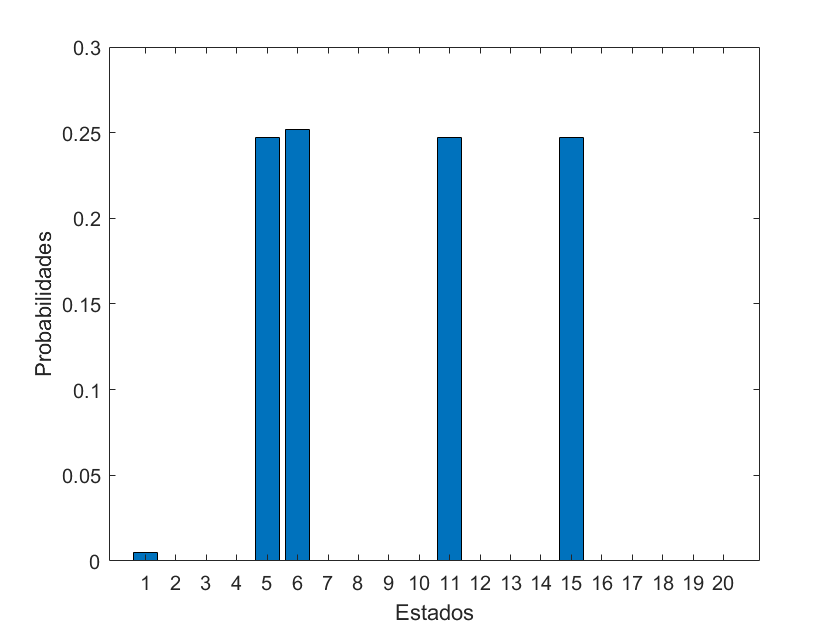


figure(); clf;
bar(pi_eq_jam);
set(gca,'XTick', 1:20);
xlabel("Estados");
ylabel("Probabilidades");

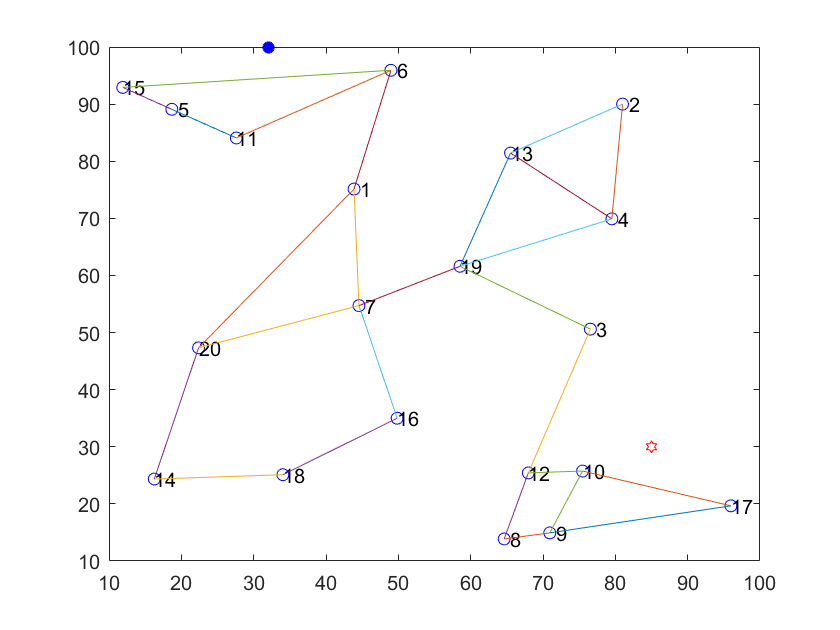


nr_samples = 1000;

seq = state_seq_gen(P_jam, nr_samples);
[~,A,b] = RSS_m1(nodePos, sourcePos, seq, ni_v); % gera RSS via metodo 1

z = A\b;

run MarkovChainDraw.m
plot(z(1),z(2),'b*', 'LineWidth', 2);

Como é possível observar, a entropia desce drasticamente, conforme seria de esperar. A estimativa da localização da fonte (circulo azul) tem um erro elevado e a observação do gráfico que mostra as probabilidades do vector de distribuição limite aparenta uma elevada discrepância e uma circulação preferencial pelos estados que foram alvo desta intervenção, que foi, claramente, bem sucedida.

## Pergunta 3a - Aplicação do Método de Monte Carlo

De maneira a testar empíricamente o que foi estudado em termos probabilísticos na alínea anterior, realizou-se o método de Monte Carlo (função : `'state_mmc_gen()'`). Este método consiste em repetir a mesma operação várias vezes e apresentar o resultado comparando com o resultado teórico obtido pela Teoria de Markov. Assim esta alínea encontra-se em coerência com o método desenvolvido anteriormente. Para que tal aconteça, após ter sido aplicado o método de Monte Carlo, transformou-se a matriz resultante [MxN] (em que [M] é o número de runs e [N], o tamanho de cada run) numa matriz com a média da probabilidade de cada estado em cada instante [N*20]. A função que permite fazer a transformação é '`state_to_probability()`',.

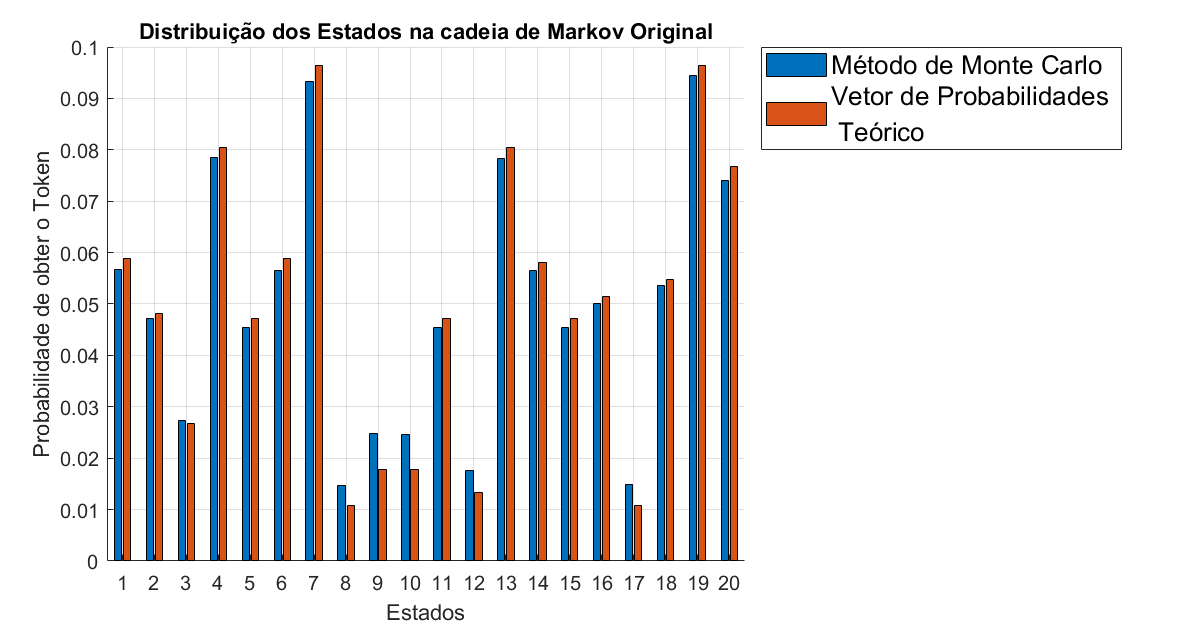

seq_MC = state_mmc_gen(P,'Original');

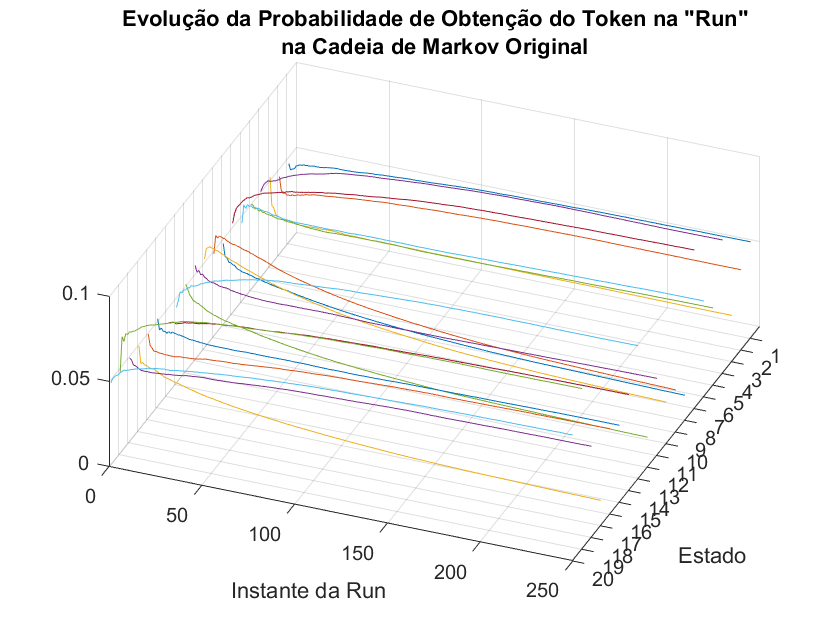

evo_mat_eq = state_to_probability(seq_MC);
MarkovTime(evo_mat_eq,'Original');

convergence_pace(evo_mat_eq,pi_eq,'Original');

A evolução da probabilidade de obtenção do token, na cadeia de Markov Original, demora em média 0.87 da "Run" a convergir para (± 0.25%) dos valores de probabilidades limite.


Analisando em detalhe o resultado referente à cadeia de Markov original, a distribuição de probabilidades, apesar de muito próxima da que foi determinada em 2, evidência que o método de Monte Carlo é ruidoso e portanto nota-se ligeiras incertezas.

Em relação à evolução temporal, é bem evidente a convergência do método para um número de runs elevado. Em particular, o ritmo de convergência foi calculado comparando com os valores de probabilidades limites. Assim, calculou-se o desvio de probabilidades de cada estado em cada instante na run, e o segredo consiste em pesar a diferença de cada estado pela probabilidade de o mesmo acontecer, pois diferencia os estados com base na sua influência na run. Este raciocínio está presente na linha 15 da função '`convergence_pace()`' (dif = abs(m-v)*v';) em que 'm' é a matriz [Nx20] e 'v' o vetor de probabilidade limite de Markov referente a cada estado [1x20].

Em contraste com a alínea 2c, esta confirmou o esperado, visto que apresentou um ritmo de convergência mais baixo. Este acontecimento deve-se ao facto do método de Monte Carlo apresentar ruído e consequentemente incertezas face aos valores limites.

De seguida repetiu-se o raciocíno em cima para as variantes do gráfico da alínea 2d.

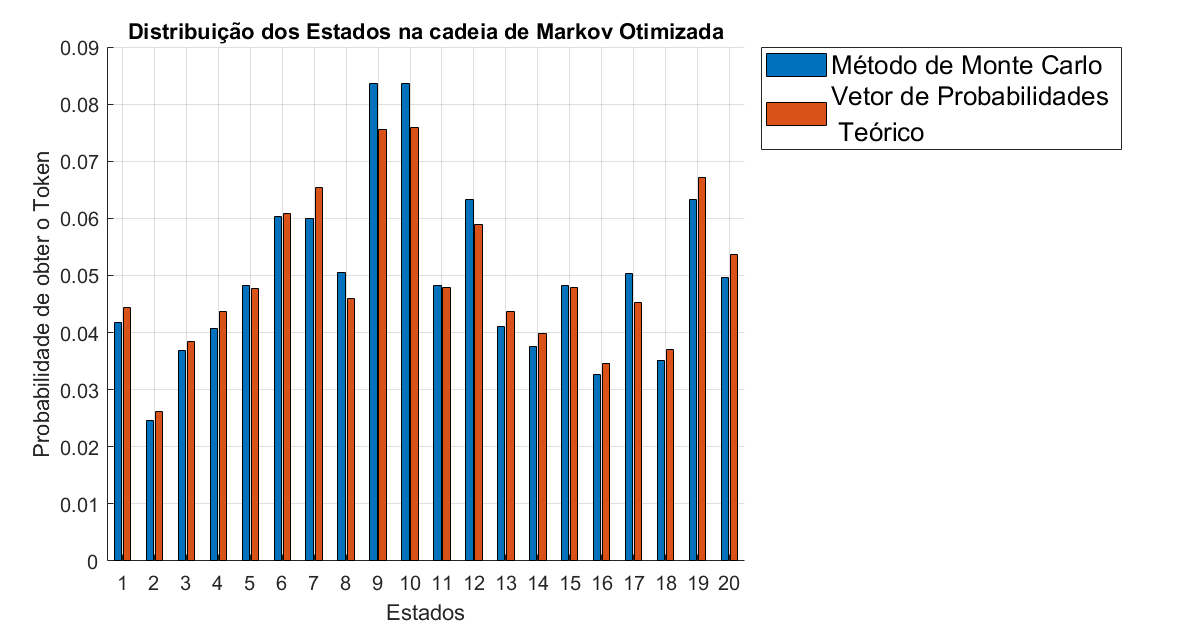

seq_MC_opt = state_mmc_gen(P_opt,'Otimizada');

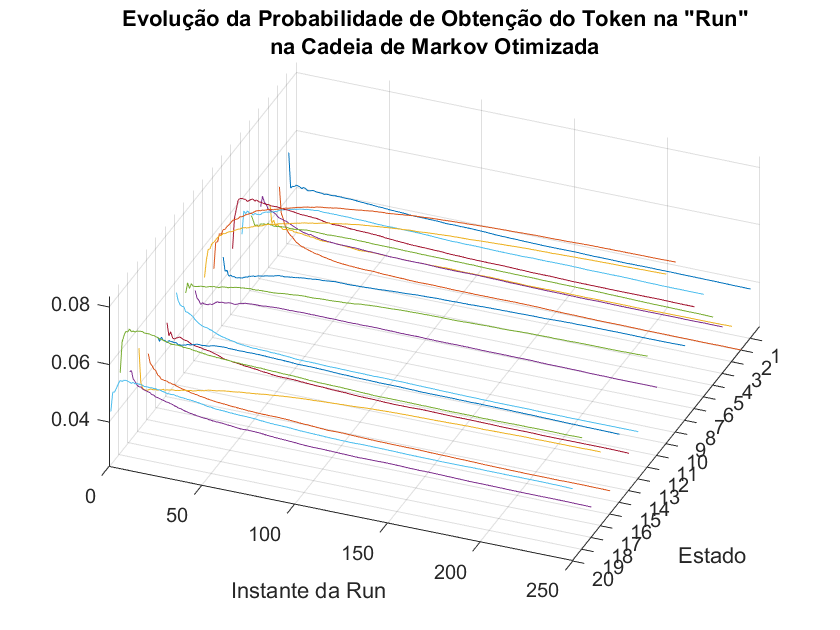

evo_mat_opt = state_to_probability(seq_MC_opt);
MarkovTime(evo_mat_opt,'Otimizada');

convergence_pace(evo_mat_opt,pi_eq_opt,'Otimizada');

A evolução da probabilidade de obtenção do token, na cadeia de Markov Otimizada, demora em média 0.08 da "Run" a convergir para (± 0.25%) dos valores de probabilidades limite.


Pelo gráfico da distribuição das probabilidades, nota-se claramente que esta cadeia está mais equilíbrada que a cadeia original e que o método de Monte Carlo faz jus ao resultado teórico previsto pela teoria de Markov.

Relativamente à evolução temporal, comparando com a cadeia de Markov original observou-se menor tempo de convergência, fruto de uma circulação mais livre do Token. É de salientar que apesar da probabilidade referente aos estados mais prováveis ainda se encontre a convergir, como a cadeia tem uma entropia altíssima, as alterações significativas ocorrem entre estados mais prováveis preservando a probabilidade dos restantes estados. Consequentemente, fruto da seleção da importância de cada estado no cálculo do ritmo de convergência, rapidamente nesta cadeia muitos estados atingem a sua probabilidade limite e portanto o ritmo de convergência é elevadissímo.

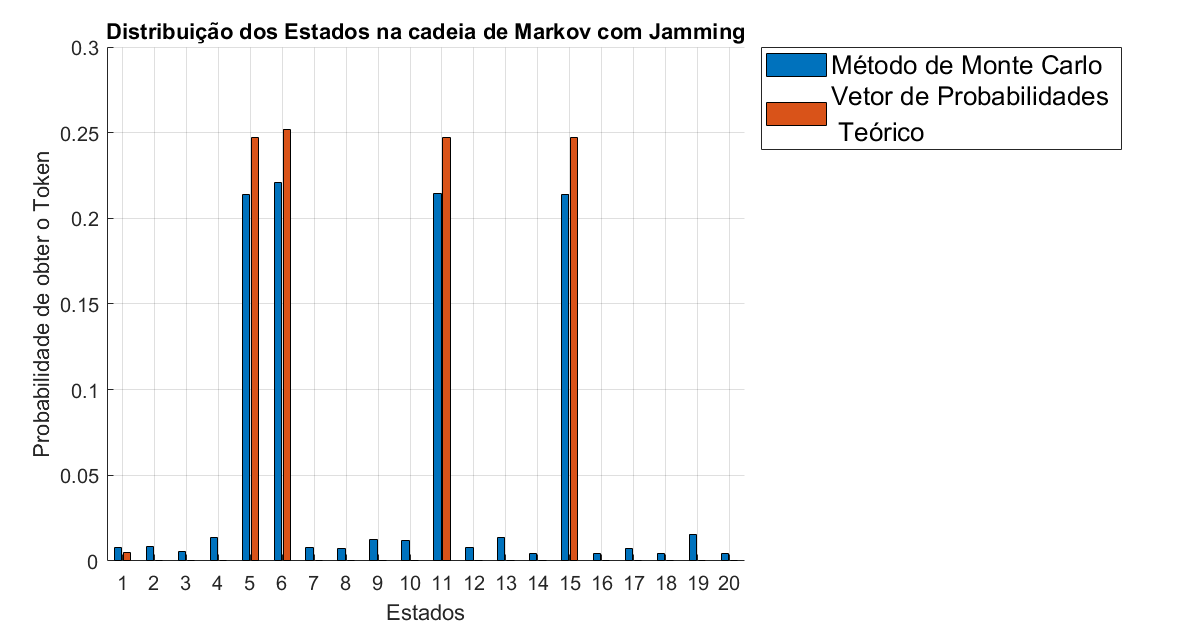

seq_MC_jam = state_mmc_gen(P_jam,'com Jamming');

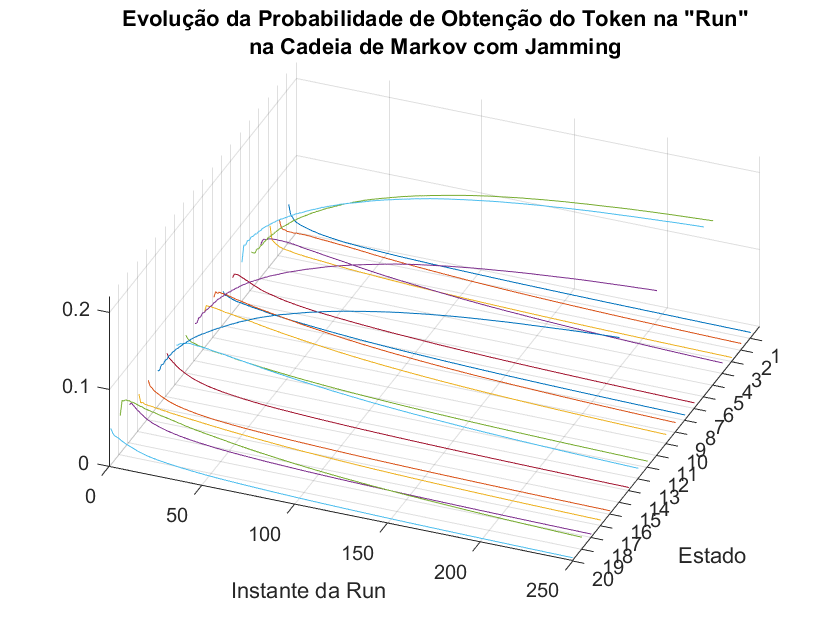

evo_mat_jam = state_to_probability(seq_MC_jam);
MarkovTime(evo_mat_jam,'com Jamming');

convergence_pace(evo_mat_jam,pi_eq_jam,'com Jamming');

A evolução da probabilidade de obtenção do token, na cadeia de Markov com Jamming, não convergiu para (± 0.25%) dos valores de probabilidades limite em 250 runs.


Por sua vez, a distribuição de probabilidades para a cadeia de Markov com Jamming encontra-se menos bem (face à determinada na pergunta 2d) fruto da disposição aleatória do estado inicial em cada run. Este acontecimento pode atrasar bastante a passagem do Token para a ilha {Estados: 6-11-5-16-6} (que praticamente o retêm).

Em relação ao ritmo de convergência, este vai ser muito demorado devido ao ruído mais que evidente do método de Monte Carlo. A permissa anterior é confirmada com os resultados obtidos: não convergência do gráfico para as mesmas condições inicias e entropia obtida.

## Pergunta 3b - Estimação do erro associado à localização (imóvel) medida vs exata da fonte (Anetna)

Nesta questão estimou-se o erro entre a distância calculada de acordo com a pergunta 2b usando (2)-(3), e a fonte (imóvel). De maneira estudar o comportamento geral da cadeia de Markov Original, simulou-se o seu comportamento e comparou-se com algumas variantes tais como a cadeia de Markov Otimizada ou com Jamming, e ainda nos casos em que a o estado inicial priviligia os estados menos prováveis.

Tendo em conta que é usado um método de triangulação, apenas apartir terceira amostra (inclusive) é que os resultados fazem sentido (nas duas primeias instâncias os erros não têm significado). Assim, é totalmente legítimo afirmar que os resultados encontram-se corretos caso se note uma convergência para 0 (caso ideal), apartir da terceira instância. De modo a facilitar a leitura (e preservando fiabilidade), apenas foi a estudo os primeiros 10% da matriz, visto que só por si têm uma estabilidade muito elevada

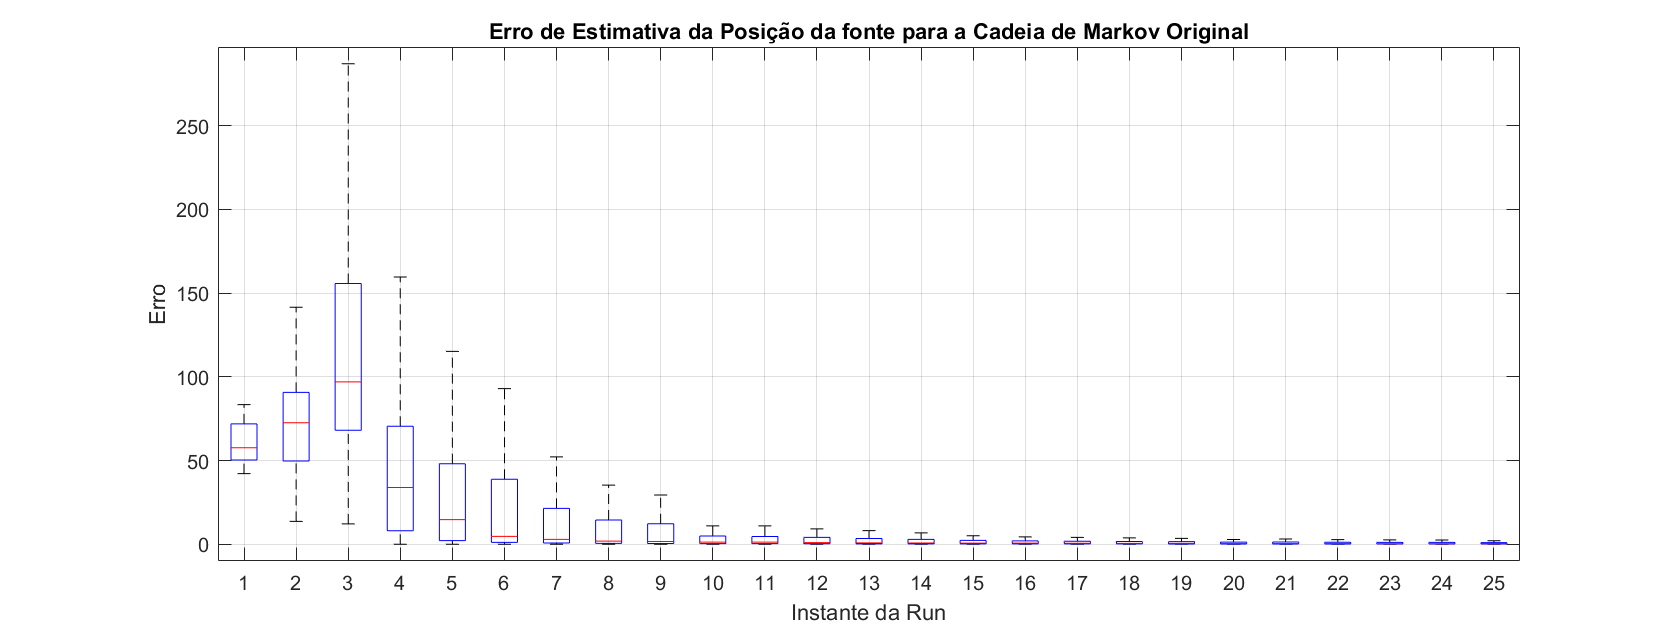

RSS_mmc(seq_MC,'Original');

Tal como previsto o erro obtido tem uma forte atenuação à medida que o token circula na rede, pois o número de amostras é maior. A convergência deste método é evidente apartir de poucos instantes, o que confirma a elevada qualidade do método.

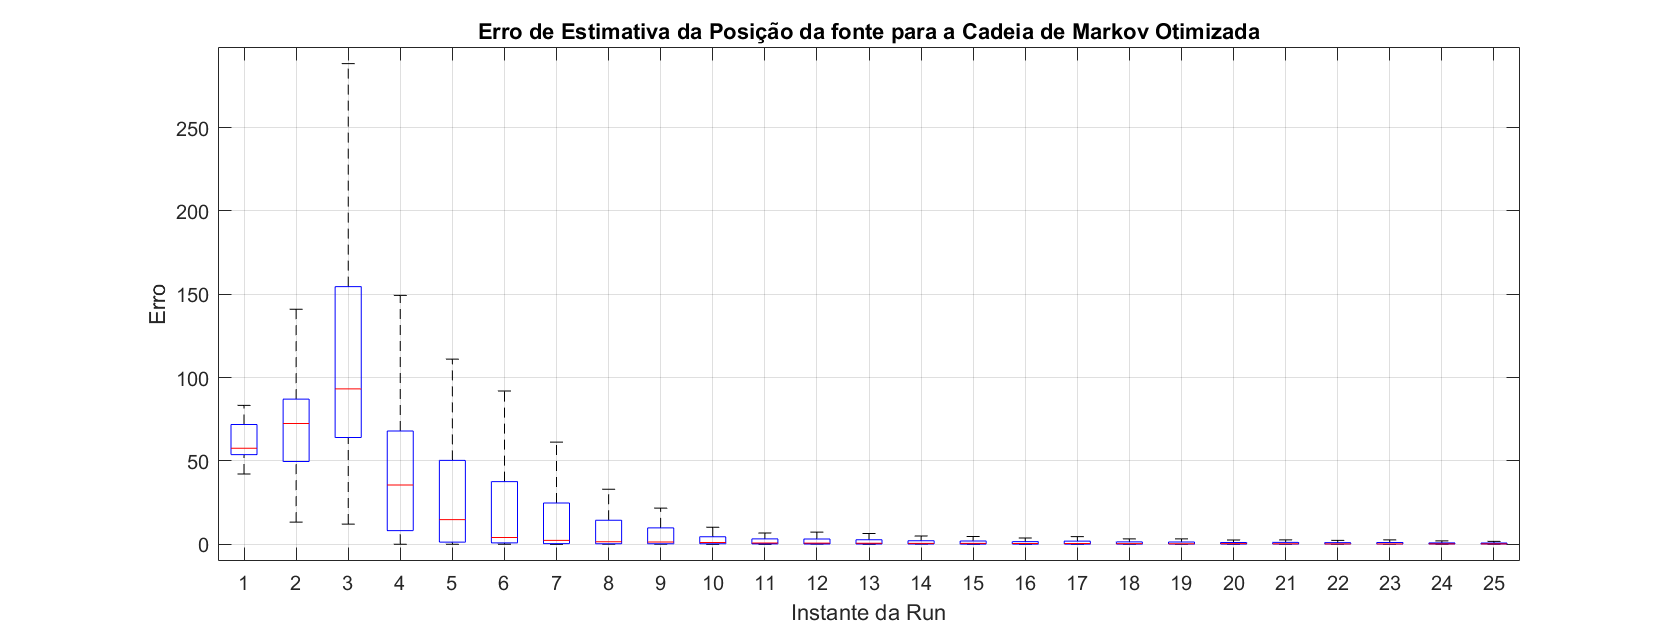

RSS_mmc(seq_MC_opt,'Otimizada');

Em comparação à estimativa do erro obtida na cadeia de Markov Original, a cadeia de Markov Otimizada apresenta um ligeira redução do erro, porém quase impercetível. O resultado está de acordo com a relação de entropia de ambas as cadeias ser muito parecido.

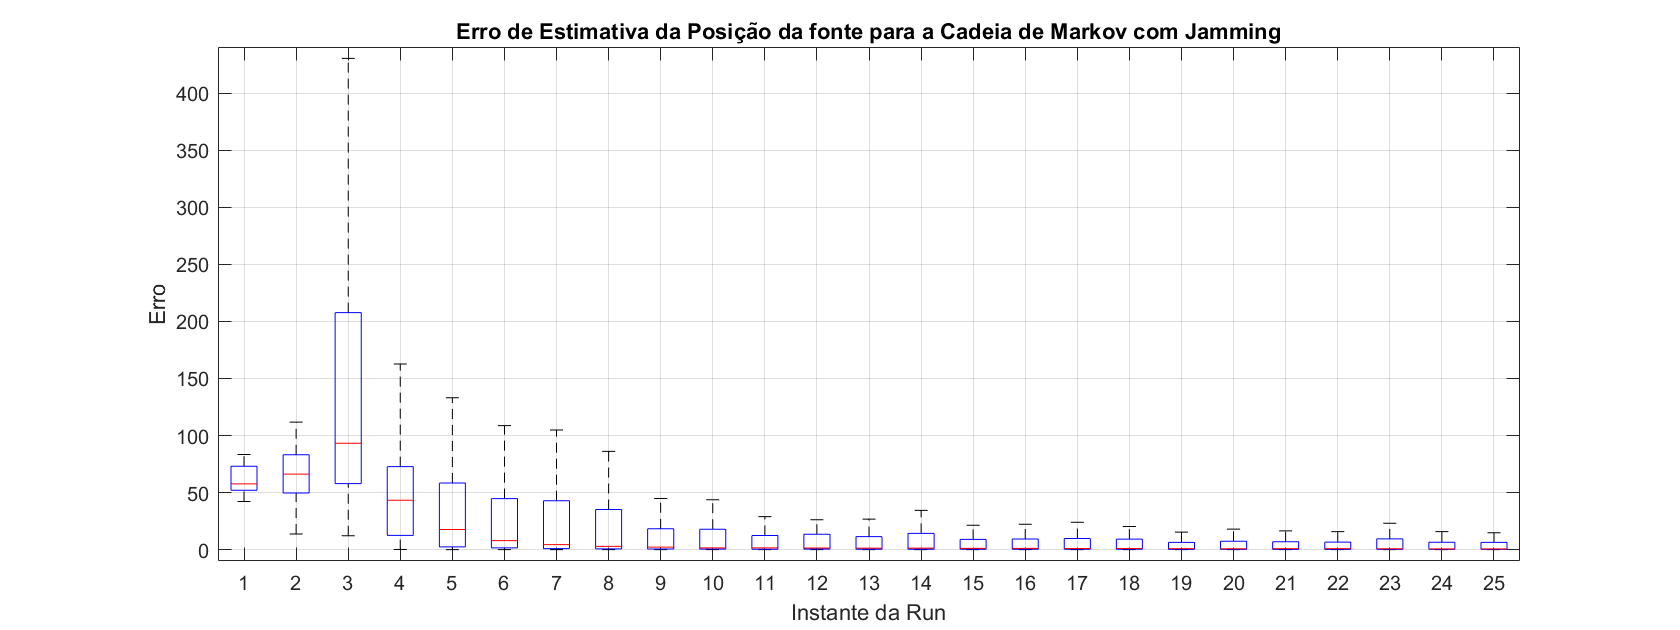

RSS_mmc(seq_MC_jam,'com Jamming');

A evolução do erro através da cadeia de Markov conincide com o esperado pois a convergência é mais demorada,visto que neste caso peca a diversidade de estados. Em particular observa-se que apartir de um certo erro este parece que estabiliza num valor perto de zero mas não nulo. Estudando a localização da ilha no Mapa, esta encontra-se distante da fonte e portanto é normal que haja um erro associado. O facto de de não haver (ou haver pouquissímas) informação de pontos geograficamente distantes inter-estados como geograficamente próximos estado-fonte, também influência no erro obtido.

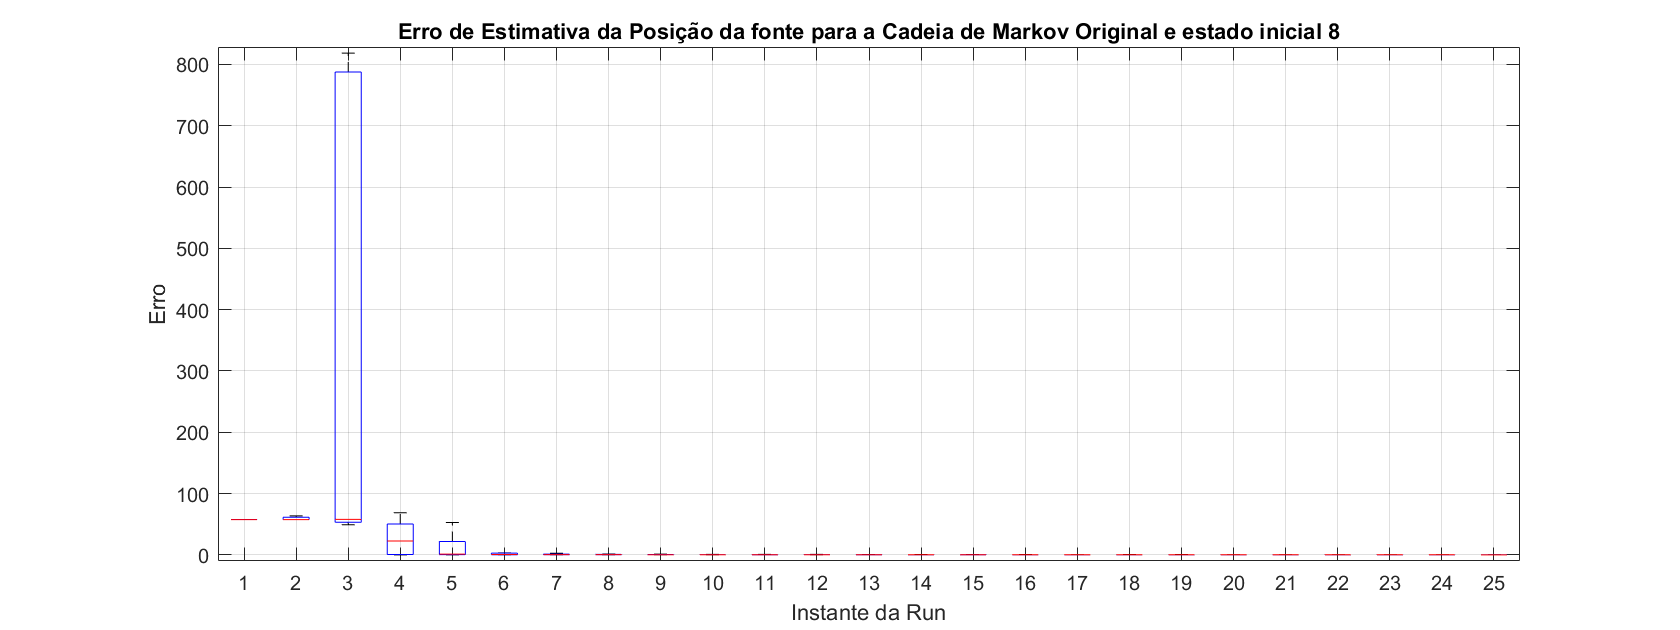

RSS_mmc(seq_MC,'Original e estado inicial 8',8);

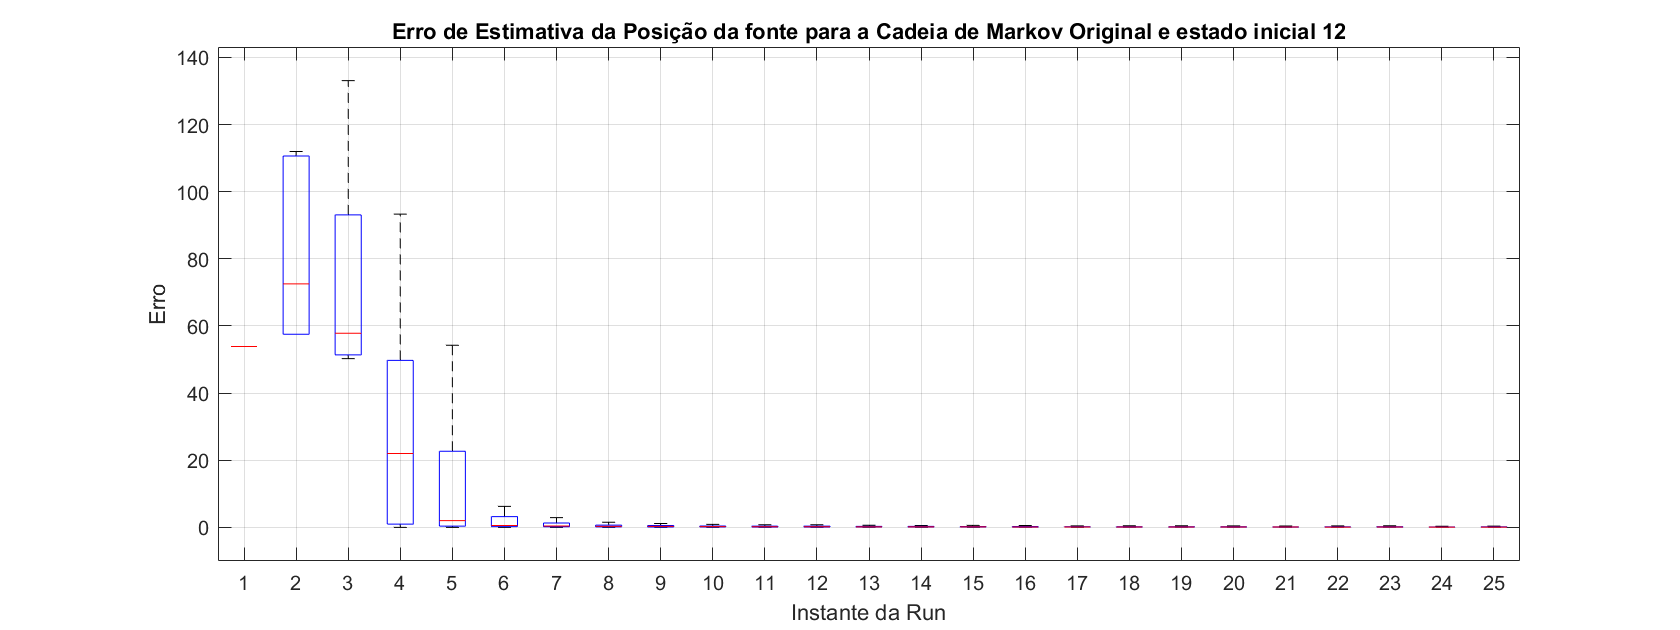

RSS_mmc(seq_MC,'Original e estado inicial 12',12);

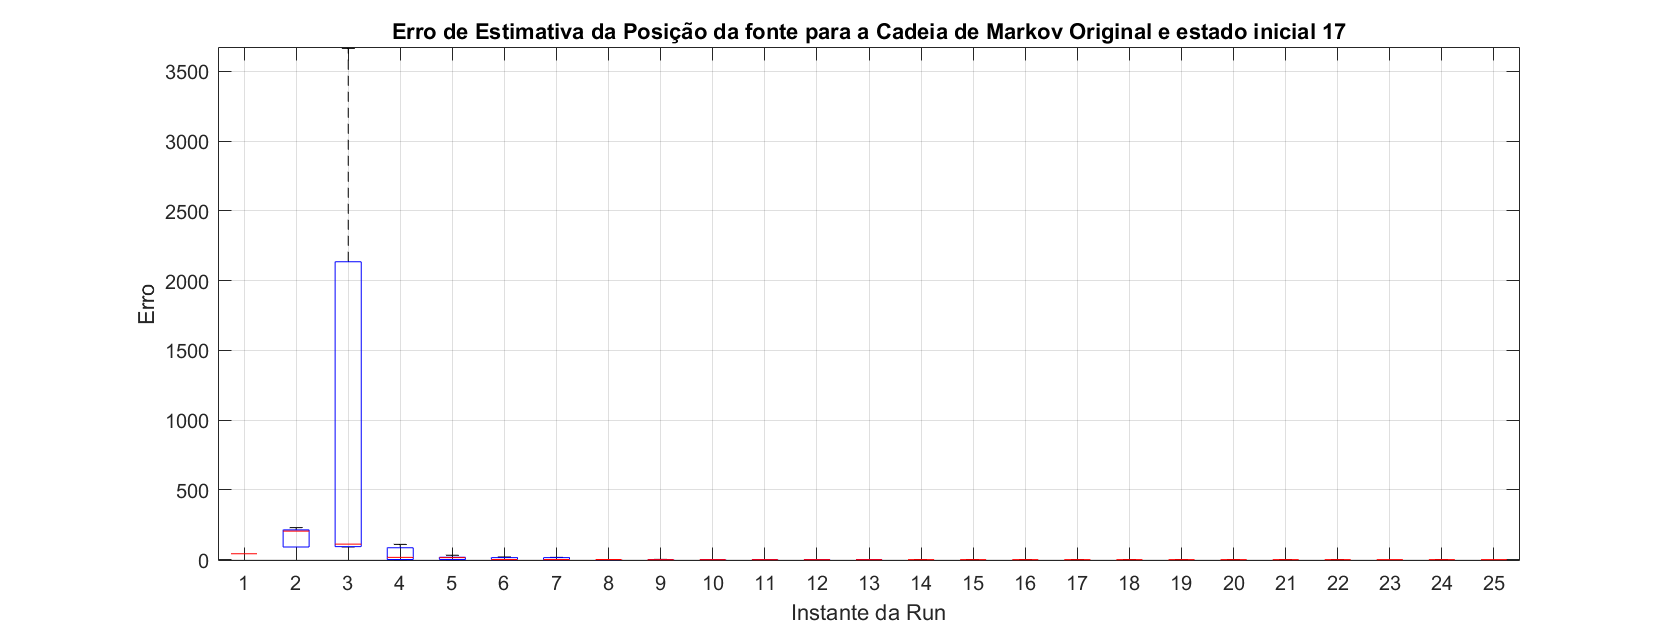

RSS_mmc(seq_MC,'Original e estado inicial 17',17);

Primeiramente observa-se que nestes casos, o primeiro instante só tem 1 valor. Isto aconetce pois o estudo consiste analisar a evolução do tempo com o estado inicial constante para cada gráfico, priviligiando um dos estados menos prováveis de obter o token posteriormente.

Nestes casos priviligiámos uma circulação inicial incomum e portanto até a run atingir a normalidade, obtemos sequências de transições de estados menos comuns. Assim a diversidade de dados recolhidos e a analisar aumenta e é natural que a convergência deste do erro tenda para 0 mais rapidamente, conforme se observa pelas figuras anteriores.

## Pergunta 3c - Estudo do fato de esquecimento $$\lambda$$, face a uma movimentação lenta da fonte (Antena)

Neste caso simulou-se uma movimentação lenta (linha 19: sourcePos = sourcePos + cumsum(2*(rand(size(y,2),2)-0.5)); (função: 'RSS_mmc()')), no máximo 1 unidade (x,y) por instante, com a posição inicial da source (85,30). O Fator de esquecimento consiste em pesar as medidas anteriores de modo que não interfiram tanto no cálculo da posição no instante presente, visto que foram obtidas para uma possível localização diferente da fonte. O fato de esquecimento $$\lambda$$ rege-se da seguinte maneira: $$\lambda^n, , \lambda \in [0 1], n \in \mathbb{N}$$

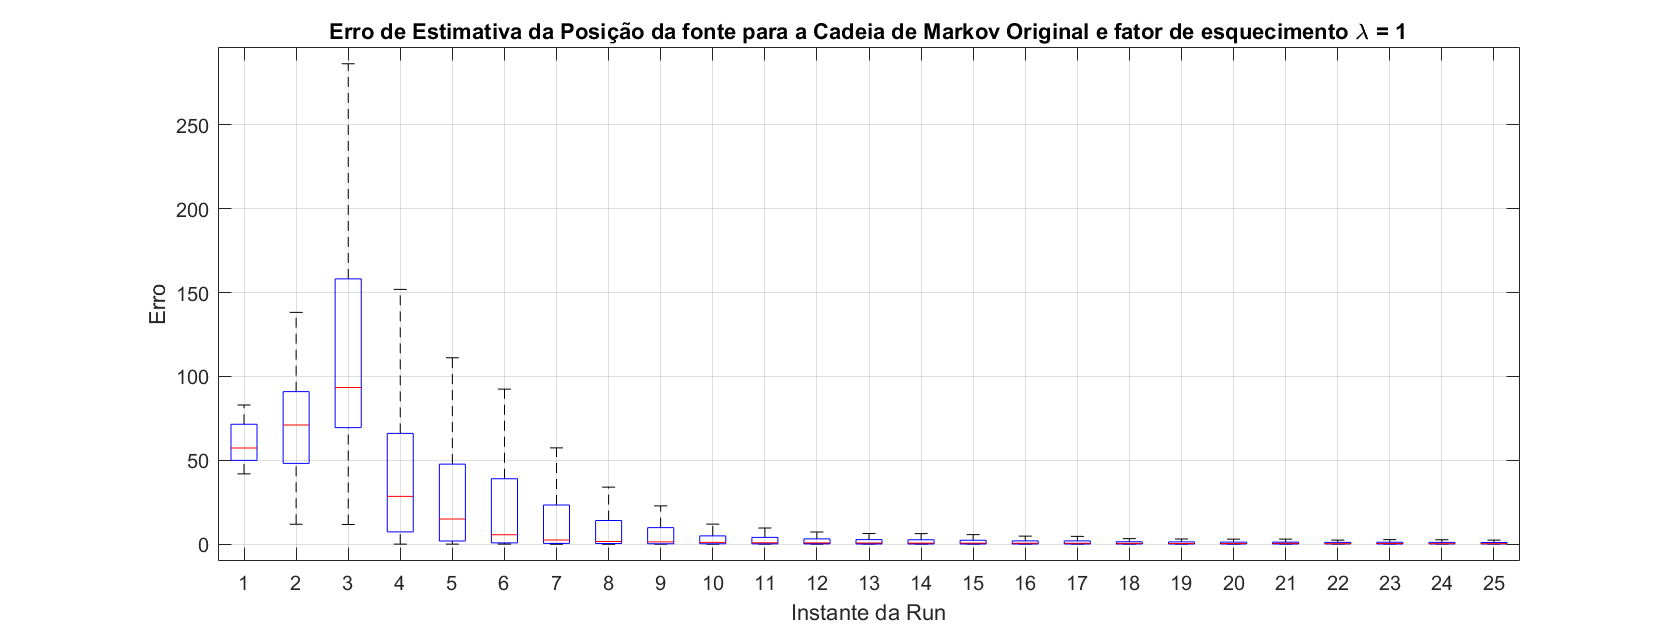

RSS_mmc(seq_MC,'Original e fator de esquecimento \lambda = 1','',1);

No primeiro caso, como o fator de esquecimento é 'nulo' e a movimentação em torno da fonte é lenta, as medidas em instantes anteriores contribuem com bastante relevância da estimativa, e portanto não é notado grande diferença para com o gráfico obtido, nas mesmas condições excepto a movimentação da fonte, da alínea anterior.

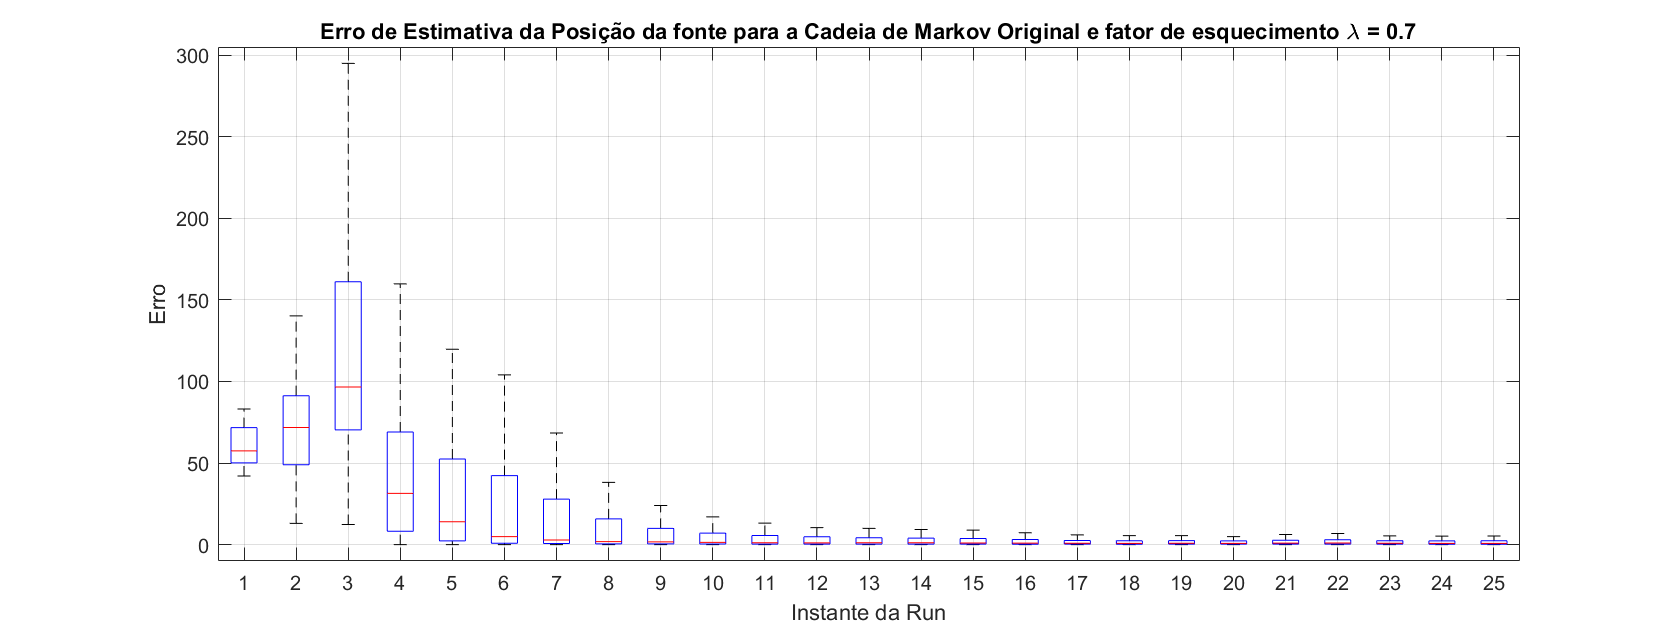

RSS_mmc(seq_MC,'Original e fator de esquecimento \lambda = 0.7','',0.7);

É pretendido agora descobrir um valor tal que melhor se apoxima-se da condição seguinte (que é válida para x=1) $\frac{x}{10}^x < 0.1 $. Por outras palavras, encontrar um algarismo que em número inteiro representa o número de instantes (n) e em número decimal o fator de esquecimento ($$\lambda$$), de forma a que o fator de esquecimento diminuísse 10 vezes ao fim de n instantes. Assim é possível prever que com $\lamdba = 0.7 $, a estimativa de erro da posição da fonte apresenta o mesmo comportamento que o previamente estudado, mas que o peso de instantes anteriores é menor. A vantagem deste método remete a numa possível implementação prática, a 'stack' não fique tão cheia pois a partir de um certo instante a informação antiga é irrelevante (peso muito baixo). Assim o método assemelha-se a uma 'moving weight average'.

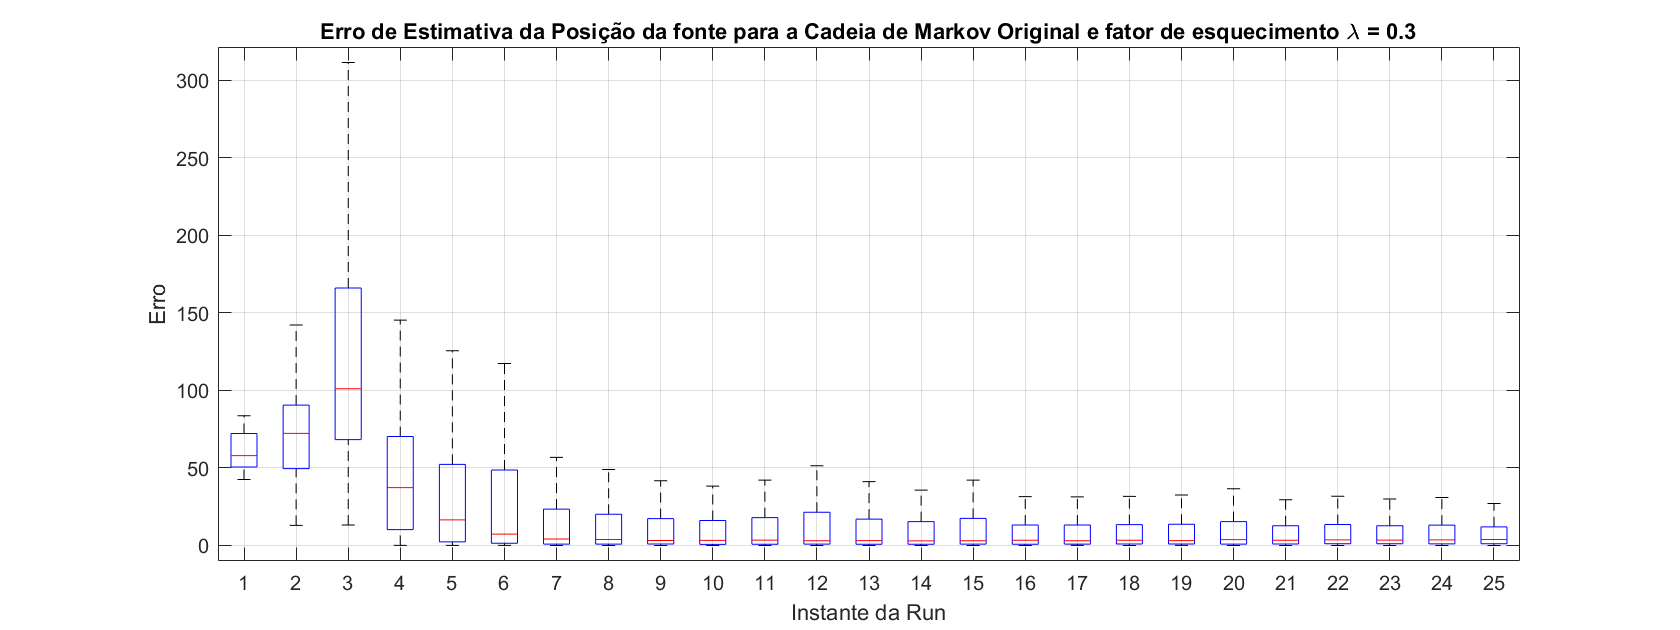

RSS_mmc(seq_MC,'Original e fator de esquecimento \lambda = 0.3','',0.3);

Finalmente, reduziu-se o fator de esquecimento para $$\lambda = 0.3 $$. Neste caso, observamos a estabilização do erro num valor distante de 0, fruto do elevado peso que os instantes recentes têm. Analisando mais profundamente, vericamos que após o pico inicial que ocorre no terceiro instante, o fator de esquecimento permite tirar da equação as primeiras medidas que não têm significado ou que apresentam erros significativos, mantendo-se a estimativa do erro aproximandamente constante logo de seguida. Referir que neste caso, os erros associados são os mais dispersos embora que a mediana (linha vermelha de cada caixa) é mais constante ao longo do tempo e apresenat valores mais baixos.